# Path planning

A mobile robot needs a goal to execute a path, however there is a lot of solution to get from point A to point B. Because that, it´s important to have a path planner  to get the best balance between safety, time, cost etc.

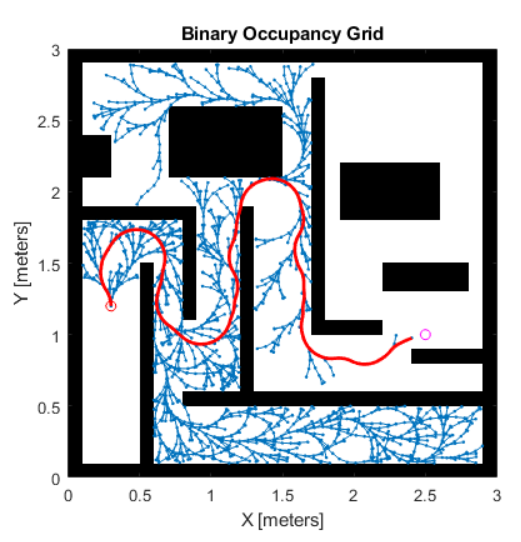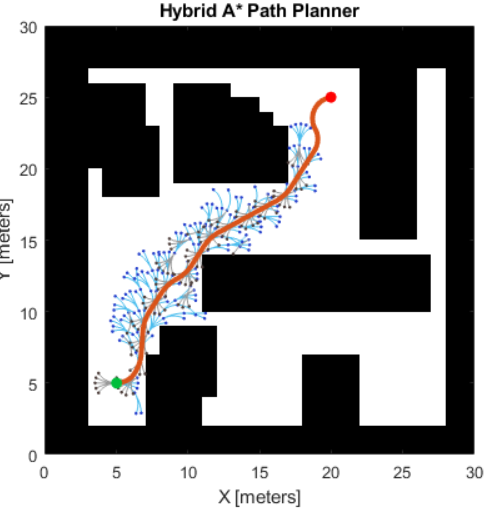

There are several algorithms to  calulate  such as [A*](https://www.mathworks.com/help/nav/ref/plannerastargrid.html), Dijkstra and  [RTT](https://www.mathworks.com/help/nav/ug/plan-mobile-robot-paths-using-rrt.html) however tere are many  algorithms variances and even thought there are several diferenth algorithms.  Rapidly-exploring random trees (RRT) is a common option that creates a graph and finds a path at the same time however the path will not necessarily be optimal. In this lesson  we will use [ RRT*](https://www.mathworks.com/help/nav/ref/plannerrrtstar.html),   is an optimized modified algorithm that aims to achieve a shortest path, whether by distance or other metrics.

Load an image, process it and convert it to binary Occupancy Map.

map = generateMap(which('world1.png'), 0.1, 10);

Define a start and goal poses.

start = [.5, 0.5,1.5707];
goal = [2, 2.5,0];

Show the start and goal positions of the robot

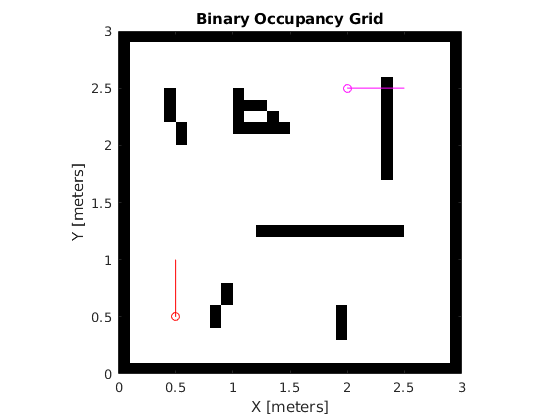

show(map)
hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

% Show the start and goal headings
r = 0.2;
plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'r-' )
plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'm-' )
hold off

Define map limits

bounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];


Define a state space as dubins. More information in [this link](https://www.mathworks.com/help/nav/ref/statespacedubins.html).

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.2;

Define a state validator object by state space.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = map;
stateValidator.ValidationDistance = .1; %Planner check if there is an obstacle between this distance in the path.

Create RRT* path planner and set parameters.


planner = plannerRRTStar(ss, stateValidator);


ContinueAfterGoalReached: This parameter allow further optimization after goal is reached, however it increase computing time.

%planner.ContinueAfterGoalReached = true;

MaxConnectionDistance: Define the maximum connection between two states in [m]

planner.MaxConnectionDistance = .02;

MaxIterations: Define number maximum iteration. (It depends on the size and shape of the map)

planner.MaxIterations = 30000;

GoalReachedFcn: Assign a function to know when stop algorithm based on distance from actual state to goal.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Define a control random number generator the seed is 1 to get the "same result" each execution.

rng(1,'twister')

Plan a path.

[pthObj, solnInfo] = plan(planner, start, goal);


Show  the path calculated by planner and tree generated.

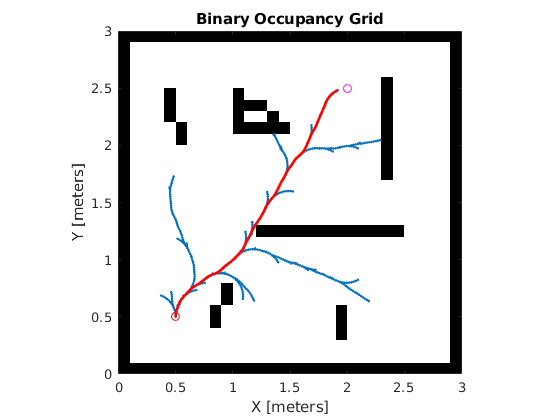

show(map)
hold on

% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');

% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

hold off

As you can see in the image above, the path is not safe because is near to walls, we can improve by expanding walls applying morphological dilation (more info at [this link](https://www.mathworks.com/help/images/ref/strel.html)):

image = imread(which('world1.png'));
grayimage = rgb2gray(image);
bwimage = grayimage < .1;

%morphological dilation
se = strel('sphere',2); % Radio in pixels
bwimage = imdilate(bwimage,se);

%Convert image into  binaryOccupancyMap  with scale  (pixes/meter).
mapDilatation = binaryOccupancyMap(bwimage,10);

Execute  same algorithm  but with dilatated map.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = mapDilatation;
stateValidator.ValidationDistance = .1; %Planner cheks if there is an obstacle between this distance in the path.
planner = plannerRRTStar(ss, stateValidator);
planner.MaxConnectionDistance = .02;
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;
rng(1,'twister')
[pthObj, solnInfo] = plan(planner, start, goal);

Show the path calculated by planner and tree generated in the dilated map.

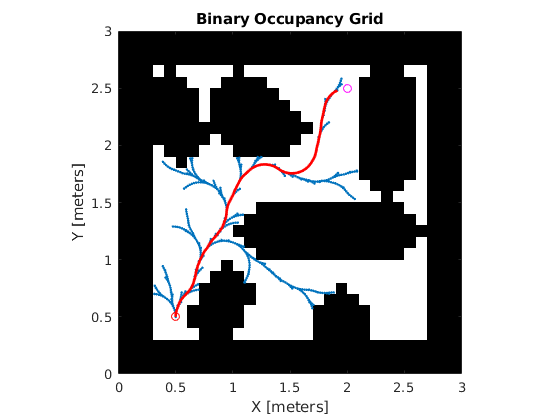

show(mapDilatation)
hold on
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');
% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)
% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

Finally show calculated path in the "real map" .

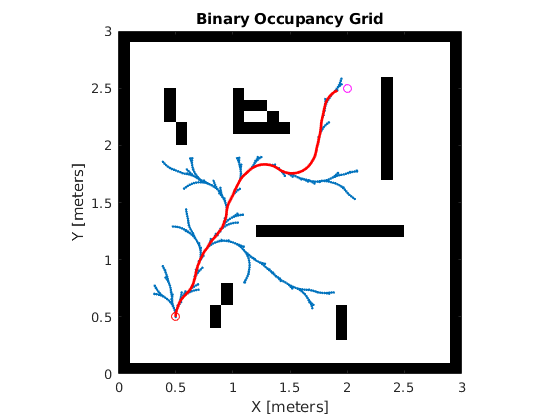

show(map)
hold on
% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');
% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)
% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

# Practice

Create a new planner with different state space for example[`stateSpaceSE2`](https://www.mathworks.com/help/nav/ref/statespacese2.html)` and `[`stateSpaceReedsShepp`](https://www.mathworks.com/help/nav/ref/statespacereedsshepp.html)`. Change parameters to get a good path.`

`Create a path with different planner (` [A*](https://www.mathworks.com/help/nav/ref/plannerastargrid.html) or [HybridAStar](https://www.mathworks.com/help/nav/ref/plannerhybridastar.html) `) and compare results.`

`--------------------------------------------`

`The function to stop RRT*`

function isReached = exampleHelperCheckIfGoal(planner, goalState, newState)
    isReached = false;
    threshold = 0.1;
    if planner.StateSpace.distance(newState, goalState) < threshold
        isReached = true;
    end
end

